clear ; close all ; clc

load('encryption_keys.mat', 'keys');
%load('EncryptedImage.mat' , 'Encrypted_img')
load('Stego_image.mat' , 'Stego_img')

% Extract the encrypted image using s and the cover image
s = 0.005 ;
cover = imread('moonsurface.tiff');
cover = imresize(cover , [256 256]);
if size(cover,3) == 3
    cover = rgb2gray(cover);
end
Encrypted_img = (Stego_img - (1-s).* double(cover))/s;

PWLCM1 = pwlcm(keys.p1 , keys.x01 , 256^2);
[~, shufling_vec] = sort(PWLCM1); % get permutation index
PWLCM2 = pwlcm(keys.p2 , keys.x02 , 256^2);
diffusing_vec = (uint8(PWLCM2 * 255))';

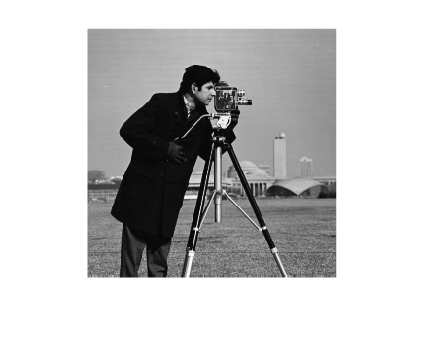

Encrypted_img_vec = Encrypted_img(:);
D1 = mod(double(Encrypted_img_vec) - double(diffusing_vec) + 256 , 256);

inv_perm = zeros(size(shufling_vec));
inv_perm(shufling_vec) = 1:length(shufling_vec);  % build inverse
D2 = D1(inv_perm);     % recover original
Decrypted_img = uint8(reshape(D2 , [256 256]));
figure ; imshow(Decrypted_img);

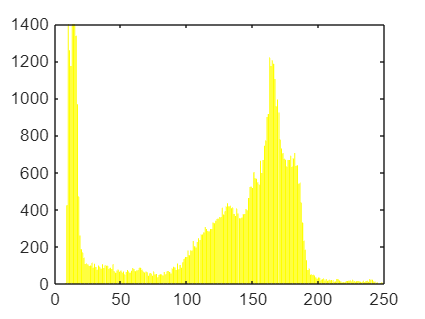

figure ; h1 = imhist(Decrypted_img) ; bar(h1, 'yellow') ; ylim([0 1400]); xlim([0 250])
yticks(0:200:1400);

I = imread('cameraman.tif');
I = imresize(I, [256 256]);
if size(I,3) == 3
    I = rgb2gray(I)
end

PSNR = psnr(I, Decrypted_img)

PSNR = 7.4142

SSI = ssim(I, Decrypted_img)

SSI = 0.3202

function x = pwlcm(p, x0, N)
    % PWLCM generator; returns 1 x N row vector with values in (0,1)
    x = zeros(1, N);
    x(1) = x0;
    for n = 1:N-1
        if x(n) < p
            x(n+1) = x(n) / p;
        else
            x(n+1) = (1 - x(n)) / (1 - p);
        end
    end
end
